# Analyzing solar flares with MATLAB and Python

## Check basic configuration   

First let's confirm that MATLAB recognizes the Python interpreter on our machine:

pyenv

Depending on our configuration we can use arguments to this function to point to a specific interpreter:

%% pyenv(Version="C:\\ruta\al\python.exe") 

Or to set the run mode to "OutOfProcess" which allows Python to be run in a separate process (for example, to prevent MATLAB from crashing if the Python code fails):

%% pyenv(ExecutionMode = "OutOfProcess")

## Basic syntax when using Python functions

All Python functions in MATLAB have the same basic syntax:

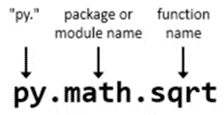

Now let's use the py syntax to call functions (py . package . function(args)); no need to use "import":

py.math.sqrt(42)

In MATLAB we can use the name=value syntax for arguments when calling Python functions. However, it is also important that we take into account the conversion of variable types:

hw = py.textwrap.wrap("Hola a todos!",width = int8(2))  %Intenta con int8 por ejemplo

Finally, convert to a MATLAB variable type if necessary:

hwML = string(hw) 

## Accessing solar flare information 

Solar flares occur when powerful magnetic fields, leaving and entering the sun, reconnect. They are usually associated with active regions, perceived as sunspots, where magnetic fields are the strongest. A scale is used to measure how large the spots and rashes are, where X is the top of the scale. X eruptions have the most potential to create problems in communication systems.

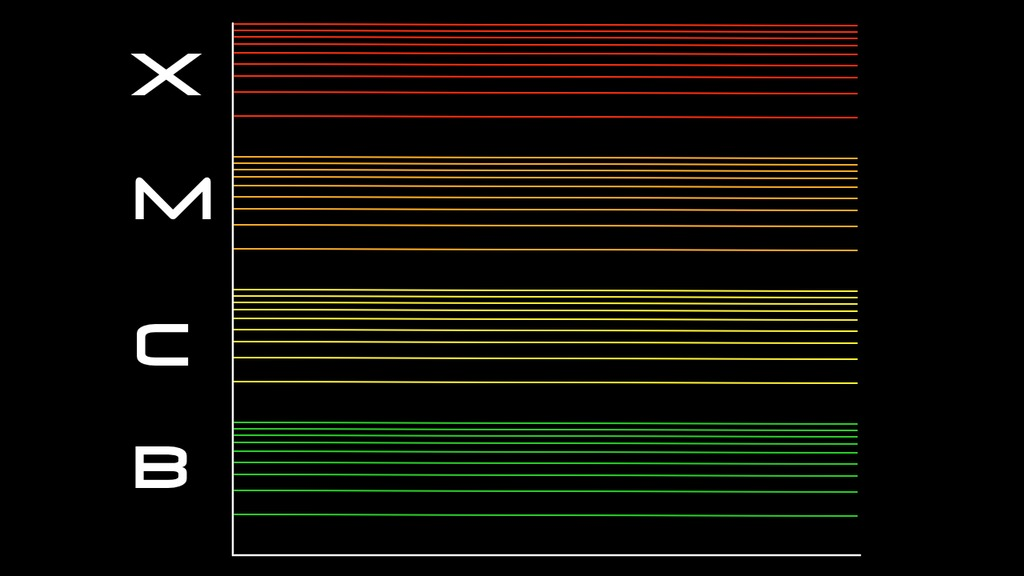

A very popular open source project to track observations of the Sun and the heliosphere is SunPy:

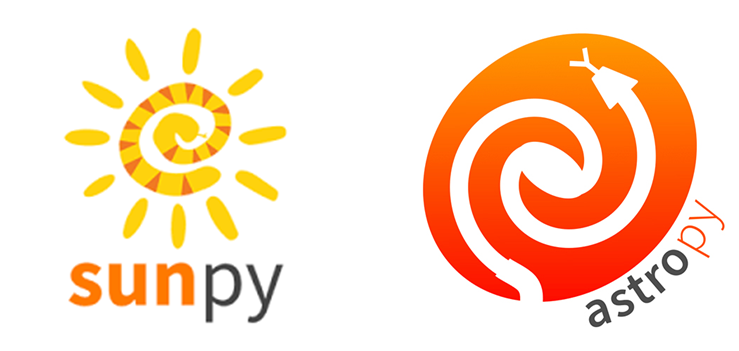

Revisemos el código Python primero!

### Check the Python code  

Let's review the Python code first!

Open the file **SolarStormPython.py** and explore its content. 

### Use the results in MATLAB

Using the Live Task to include Python code we can make the process of using this file easier.  You can find the "Run Python Code" Live Task in the LIVE EDITOR tab, under "Task"

We can review the output of the previous code segment by typing 'filtered_results' in the code cell below, and running the cell:

Now you can convert the pandas dataframe to a MATLAB table (starting on R2024a):

md = table(results_pandas)

And we can inspect the table elements in more detail:

class(md.hpc_radius)

How can I use this solar flare information? Since X-rays from the strongest flares disrupt the ionosphere, it is important to understand how this impacts the design of communications systems.